# Play with Sine Waves in Time/Frequency domains

*by Saeed Mohagheghi*

*May 20, 2019*

## 1- Create Sine wave

**Formula:**$y=a\cdot \mathrm{Sin}\left(2\pi \mathrm{ft}\right)$

*f is the frequency in Hz.*

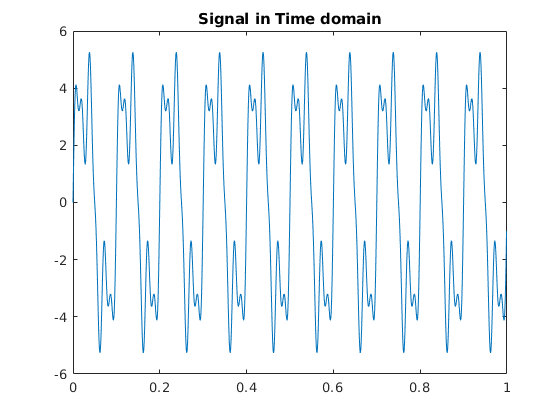

clear; close all

% First create t, then y
Fs = 1000;              % sample per second
L = 1;                  % second(s)
t = 0:1/Fs:L-1/Fs;

f1 = 10;                % Hz
f2 = 30;                % Hz
f3 = 60;                % Hz
y1 = 4*sin(2*pi*f1*t);
y2 = 2*sin(2*pi*f2*t);
y3 = 1*sin(2*pi*f3*t);

yt = y1 + y2 + y3;

plot(t,yt);
title('Signal in Time domain')

## 2- Calculate FFT

*Look for the "fft" in Matlab help for more details*

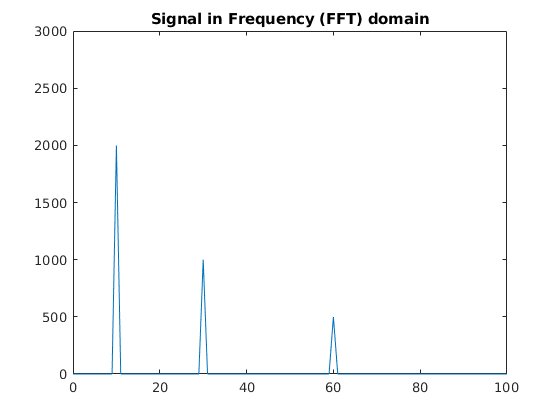

ff = fft(yt);
ff = abs(ff);           % we don't need the phase (imaginary) part
N = length(ff);
ff = ff(1:N/2);         % we also don't need the negative part

figure
x_ff = (0:N/2-1).*Fs/N; % calculate the correct x axis
plot(x_ff, ff)
xlim([0 100])
ylim([0 3000])
title('Signal in Frequency (FFT) domain')

## `3- Find Frequency Peaks`

*Look for the "findpeaks" in Matlab help for more details*

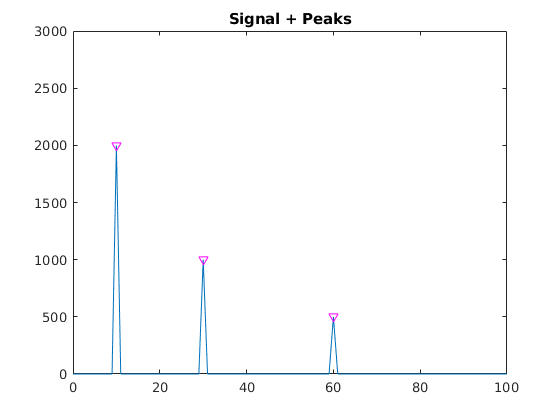

[pks, locs] = findpeaks(ff, 'Threshold', 10);
locs = (locs-1).*Fs/N;  % calculate the correct locations
plot(x_ff, ff)
hold on
plot(locs, pks, 'mv')
xlim([0 100])
ylim([0 3000])
title('Signal in Frequency domain + Peaks')


fprintf('Frequencies = %d, %d, %d', locs)

Frequencies = 10, 30, 60

## 4- Random noise in Time and Frequency domains

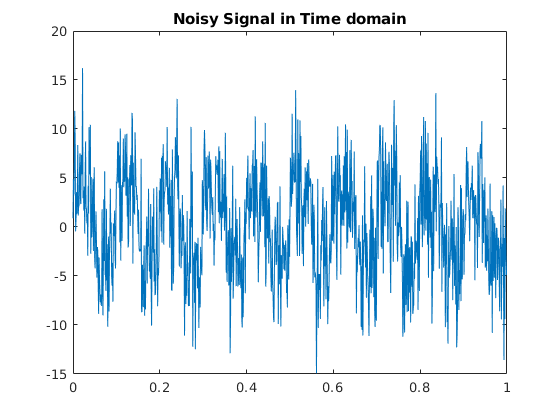

noise = 4*randn(1,length(yt));
yt_noisy = yt + noise;

figure
plot(t, yt_noisy)
title('Noisy Signal in Time domain')

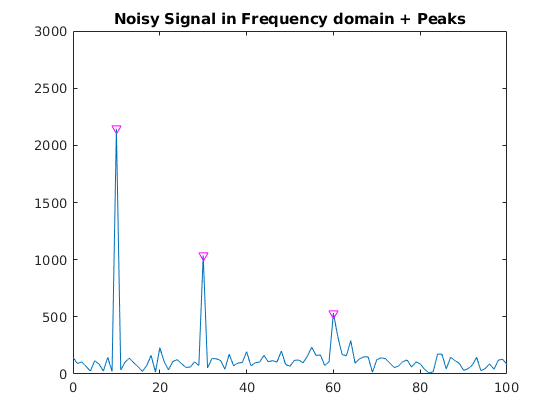


ff_noisy = fft(yt_noisy);
ff_noisy = abs(ff_noisy);           % we don't need the phase (imaginary) part
N = length(ff_noisy);
ff_noisy = ff_noisy(1:N/2);         % we also don't need the negative part

figure
x_ff = (0:N/2-1).*Fs/N;   % calculate the correct x axis
plot(x_ff, ff_noisy)
xlim([0 100])
ylim([0 3000])

[pks, locs] = findpeaks(ff_noisy, 'MinPeakHeight', 400);
locs = (locs-1).*Fs/N;  % calculate the correct locations
hold on
plot(locs, pks, 'mv')
title('Noisy Signal in Frequency domain + Peaks')


fprintf(' Frequencies = %d, %d, %d', locs)

 Frequencies = 10, 30, 60